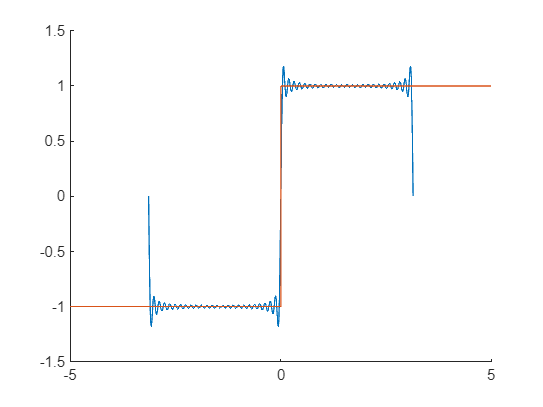

f = @sign;

T=2*pi; N=100;
k=(-N/2:N/2)';
x = linspace(-T/2, T/2, 1000); % Define x in the interval [-pi, pi]

c=zeros(length(k),1);
for idx= 1:length(k)
    c(idx) = 1/T * integral(@(x) f(x).* exp(-1i*k(idx)*x),-T/2,T/2);
end

S1=zeros(size(x));
for idx=1:length(k)
    S1=S1+c(idx)*exp(1i*k(idx)*x);
end

clf; hold on;
plot(x, real(S1));
fplot(f);
hold off;


%Estimate the error numerically
e=abs(f(x)- real(S1));
norm(e)

ans = 3.0216

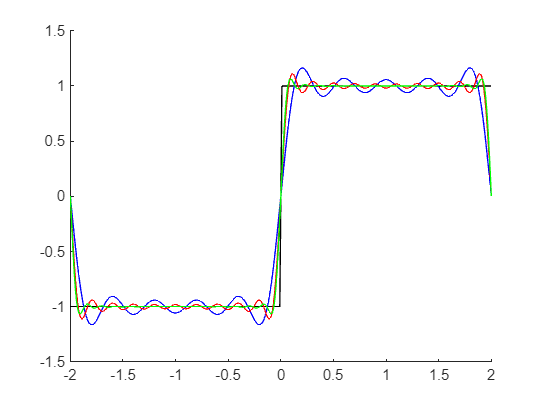

%Exercise 4 - Estimate numerically a function

%Taking Example from this code
T=4; Nmax=60; fun=@sign; x=linspace(-T/2,T/2,401); ytrue=fun(x);
tj=linspace(-T/2,T/2,Nmax+1)'; fj=fun(tj); % 61 samples of f(x)
f=[.5*(fj(1)+fj(end)); fj(2:end-1)];
c=fftshift(fft(f)); c=[c; c(1)]/Nmax; %c: column vector
c(2:2:end) = -c(2:2:end);

m=Nmax/2+1; % middle index
N1=Nmax/3; % 21
S1=exp(-1i*N1*pi/T*x).*polyval(flipud(c(m-N1/2:m+N1/2)),exp(2i*pi/T*x));

N2=Nmax*2/3; % 41
S2=exp(-1i*N2*pi/T*x).*polyval(flipud(c(m-N2/2:m+N2/2)),exp(2i*pi/T*x));

N3=Nmax; % 61
S3=exp(-1i*N3*pi/T*x).*polyval(flipud(c(m-N3/2:m+N3/2)),exp(2i*pi/T*x));

clf; hold on;
plot(x,ytrue,'k',x,real(S1),'b',x,real(S2),'r',x,real(S3),'g');
hold off;

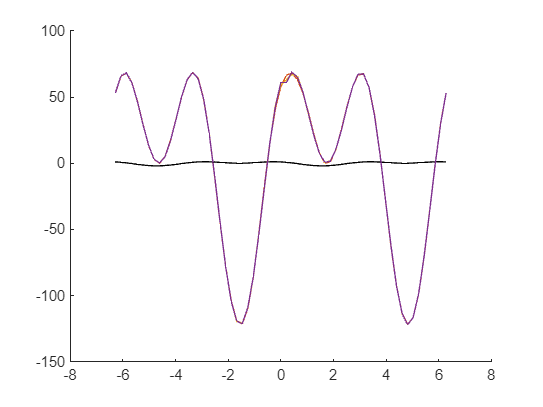

a=pi/2 - 2*pi;
b=pi/2 + 2*pi;
T=b-a;
Nmax=60;
x=linspace(-T/2,T/2,Nmax+1);
f=@(x) cos(2*x)-sin(x); %The function to estimate numerically

c=fftshift(fft(f(x)));

m=Nmax/2+1;
N1=Nmax/3;
S1=zeros(length(N1));
S1=exp(-1i*N1*pi/T*x).*polyval(flipud(c(m-N1/2:m+N1/2)),exp(2i*pi/T*x));

N2=Nmax*2/3; % 41
S2=zeros(length(N1));
S2=exp(-1i*N2*pi/T*x).*polyval(flipud(c(m-N2/2:m+N2/2)),exp(2i*pi/T*x));

N3=Nmax; % 61
S3=zeros(length(N1));
S3=exp(-1i*N3*pi/T*x).*polyval(flipud(c(m-N3/2:m+N3/2)),exp(2i*pi/T*x));

clf; hold on;
plot(x,f(x),'Color','black');
plot(x,real(S1));
plot(x,real(S2));
plot(x,real(S3));
hold off;

% Compute the Fourier coefficients of the derivative
c=fftshift(fft(f(x)));
interval=(-Nmax/2:Nmax/2);
c_deriv= 1i*(-Nmax/2:Nmax/2).*c;

% Reconstruct the partial sums for the derivative
S1_deriv=exp(-1i*N1*pi/T*x).*polyval(flipud(c_deriv(m-N1/2:m+N1/2)),exp(2i*pi/T*x));

S2_deriv=exp(-1i*N2*pi/T*x).*polyval(flipud(c_deriv(m-N2/2:m+N2/2)),exp(2i*pi/T*x));
S3_deriv=exp(-1i*N3*pi/T*x).*polyval(flipud(c_deriv(m-N3/2:m+N3/2)),exp(2i*pi/T*x));


% Compute the true derivative of the function
f_deriv = @(x) -2*cos(2*x) - cos(x);
syms t; f_sym = sym(cos(2*t)-sin(t));
f_deriv_sym = diff(f_sym)

$$f\_deriv\_sym = -2\,\sin\left(2\,t\right)-\cos\left(t\right)$$

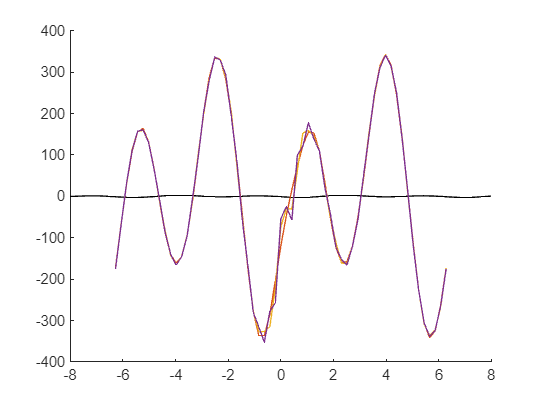



clf; hold on;
fplot(f_deriv_sym,'Color','black');
plot(x,real(S1_deriv));
plot(x,real(S2_deriv));
plot(x,real(S3_deriv));
hold off;

%Second derivative - as before
f_2deriv_sym = diff(f_deriv_sym)

$$f\_2deriv\_sym = \sin\left(t\right)-4\,\cos\left(2\,t\right)$$

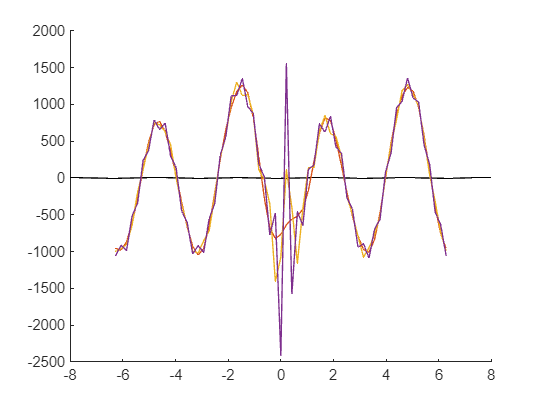

c_2deriv=1i*(-Nmax/2:Nmax/2).*c_deriv;

% Reconstruct the partial sums for the derivative
S1_2deriv=exp(-1i*N1*pi/T*x).*polyval(flipud(c_2deriv(m-N1/2:m+N1/2)),exp(2i*pi/T*x));

S2_2deriv=exp(-1i*N2*pi/T*x).*polyval(flipud(c_2deriv(m-N2/2:m+N2/2)),exp(2i*pi/T*x));
S3_2deriv=exp(-1i*N3*pi/T*x).*polyval(flipud(c_2deriv(m-N3/2:m+N3/2)),exp(2i*pi/T*x));

clf; hold on;
fplot(f_2deriv_sym,'Color','black');
plot(x,real(S1_2deriv));
plot(x,real(S2_2deriv));
plot(x,real(S3_2deriv));
hold off;